# 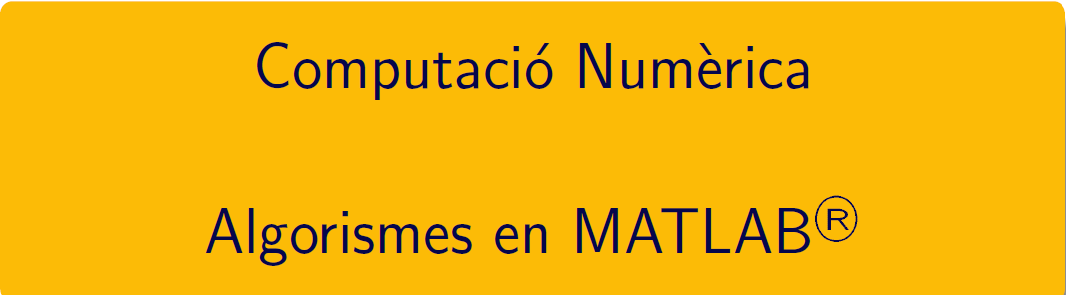

# Pràctica 1 - Conceptes Bàsics

## 1. Introducció a MATLAB

[ Cleve’s Corner: Cleve Moler on Mathematics and Computing](https://blogs.mathworks.com/cleve/)

[A Brief History of MATLAB](https://es.mathworks.com/company/newsletters/articles/a-brief-history-of-matlab.html?s_tid=srchtitle)

## 2. Exemple mètode iteratiu: convergència 

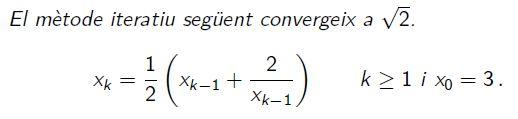

Calculeu els sis primers iterats, totes les iteracions en un vector, resultat en una estructura table.

format longG
x(1) = 3;
for k = 2:7
    x(k) = (x(k-1)+2/x(k-1))/2;
end
ea = abs(x-sqrt(2));
er = ea / sqrt(2);
R = [x; ea; er]';
T = array2table(R,...
    'VariableNames',{'x_k','ea_k','er_k'}); disp(T)

          x_k                   ea_k                    er_k        
    ________________    ____________________    ____________________

                   3         1.5857864376269        1.12132034355964
    1.83333333333333       0.419119770960238       0.296362432175337
    1.46212121212121       0.047907649748117      0.0338758240076035
     1.4149984298948    0.000784867521707922    0.000554985146932751
     1.4142137800472    2.17674102520604e-07    1.53918833981015e-07
    1.41421356237311    1.66533453693773e-14    1.17756934401283e-14
    1.41421356237309    2.22044604925031e-16    1.57009245868377e-16



## 5. Algorismes: Estabilitat numèrica i problemes ben condicionats

### Funcions

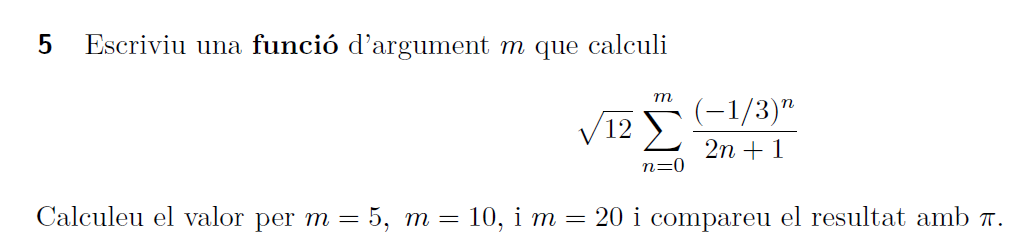

format longG
S5 = sumapi(5); S10 = sumapi(10); S20 = sumapi(20);
R = [S5,S10,S20]; r = abs(R-pi); R=[R;r]';
T = array2table(R,...
    'VariableNames',{'S','|S-pi|'},'RowNames',{'m=5','m=10','m=20'}); disp(T)

                   S                   |S-pi|       
            ________________    ____________________

    m=5     3.14130878546288    0.000283868126909947
    m=10    3.14159330450308     6.5091328815825e-07
    m=20    3.14159265359564    5.84199355557757e-12



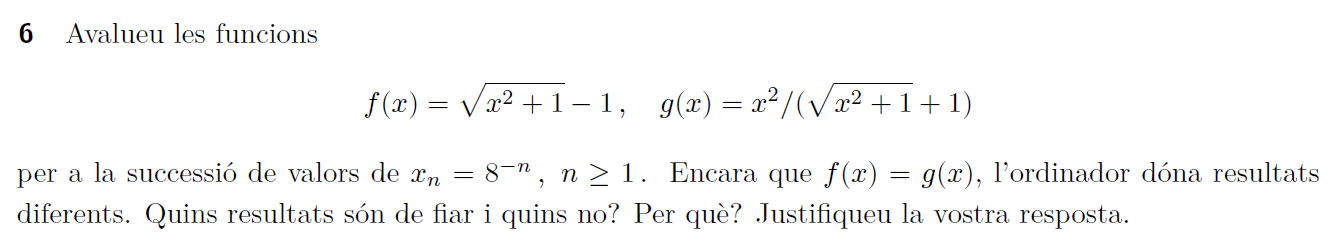

format shortG
f = @(x) sqrt(x.^2 + 1)-1;
g = @(x) x.^2./(sqrt(x.^2+1)+1);
n = 1:15;
x = 8.^(-n);
R = [n; x; f(x); g(x)]';
T = array2table(R, ...
    'VariableNames',{'n','8^(-n)','f(8^-n)','g(8^-n)'}); disp(T)

    n       8^(-n)       f(8^-n)       g(8^-n)  
    __    __________    __________    __________

     1         0.125     0.0077822     0.0077822
     2      0.015625    0.00012206    0.00012206
     3     0.0019531    1.9073e-06    1.9073e-06
     4    0.00024414    2.9802e-08    2.9802e-08
     5    3.0518e-05    4.6566e-10    4.6566e-10
     6    3.8147e-06     7.276e-12     7.276e-12
     7    4.7684e-07    1.1369e-13    1.1369e-13
     8    5.9605e-08    1.7764e-15    1.7764e-15
     9    7.4506e-09             0    2.7756e-17
    10    9.3132e-10             0    4.3368e-19
    11    1.1642e-10             0    6.7763e-21
    12    1.4552e-11             0    1.0588e-22
    13     1.819e-12             0    1.6544e-24
    14    2.2737e-13             0    2.5849e-26
    15    2.8422e-14             0     4.039e-28



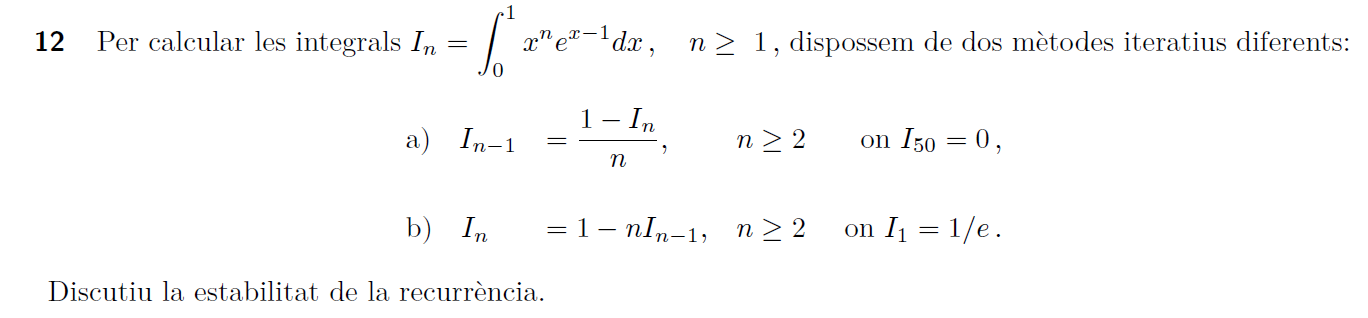

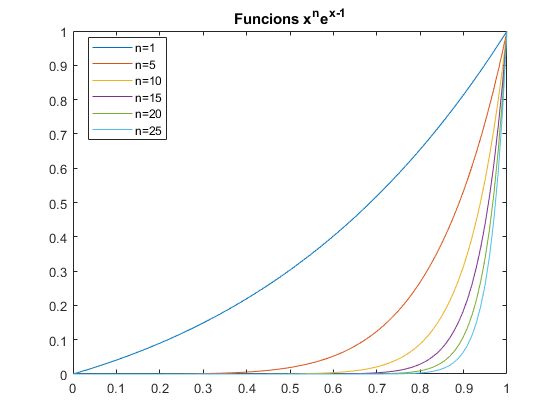

% a) correcte b) incorrecte
g = @(x,n) x.^n.*exp(x-1);
x = linspace(0,1);
plot(x,g(x,1)), hold on
for n = 1:5
    plot(x,g(x,n*5))
end
hold off
title('Funcions x^ne^{x-1}'),legend('n=1','n=5','n=10','n=15','n=20','n=25','Location','best')

- apartat a)

J(50) = 0;
for n = 50:-1:2
    J(n-1) = (1-J(n))/n;
end

- apartat b)

I(1) = exp(-1);
for n = 2:50
    I(n) = 1-n*I(n-1);
end

- valor aproximat per integració numèrica

for n = 1:50
    ve(n) = integral(@(x)x.^n.*exp(x-1),0,1);
end

- taula comparativa de resultats

n = 1:50;
R = [n; ve; J; I]';
T = array2table(R,...
    'VariableNames',{'n','ve','apartat a)','apartat b)'}); disp(T)

    n        ve       apartat a)    apartat b) 
    __    ________    __________    ___________

     1     0.36788      0.36788         0.36788
     2     0.26424      0.26424         0.26424
     3     0.20728      0.20728         0.20728
     4     0.17089      0.17089         0.17089
     5     0.14553      0.14553         0.14553
     6      0.1268       0.1268          0.1268
     7     0.11238      0.11238         0.11238
     8     0.10093      0.10093         0.10093
     9    0.091612     0.091612        0.091612
    10    0.083877     0.083877        0.083877
    11    0.077352     0.077352        0.077352
    12    0.071773     0.071773        0.071773
    13    0.066948     0.066948        0.066948
    14    0.062732     0.062732        0.062731
    15    0.059018     0.059018        0.059034
    16    0.055719     0.055719        0.055459

- taula comparativa d'errors

Re = [n;abs(ve-J); abs(ve-I)]';
Te = array2table(Re,...
    'VariableNames',{'n','apartat a)','apartat b)'}); disp(Te)

    n     apartat a)    apartat b)
    __    __________    __________

     1    5.5511e-17    5.5511e-17
     2    5.5511e-17    5.5511e-17
     3    5.5511e-17    1.1102e-16
     4             0    2.7756e-16
     5    2.7756e-17    1.4988e-15
     6             0    8.9373e-15
     7    1.3878e-17    6.2658e-14
     8             0    5.0113e-13
     9    1.3878e-17    4.5102e-12
    10    1.3878e-17    4.5101e-11
    11    1.3878e-17    4.9612e-10
    12    1.3878e-17    5.9534e-09
    13    1.3878e-17    7.7394e-08
    14             0    1.0835e-06
    15    6.9389e-18    1.6253e-05
    16    6.9389e-18    0.00026004
    17    1.3878e-17     0.0044208
    18    6.9389e-18      0.079574
    19    6.9389e-18        1.5119
    20    1.3878e-17        30.238
    21             0           635
    22    6.9389e-18         13970
    23    6.9389e-18    3.2131e+05
    24             0  

## Pràctica

## 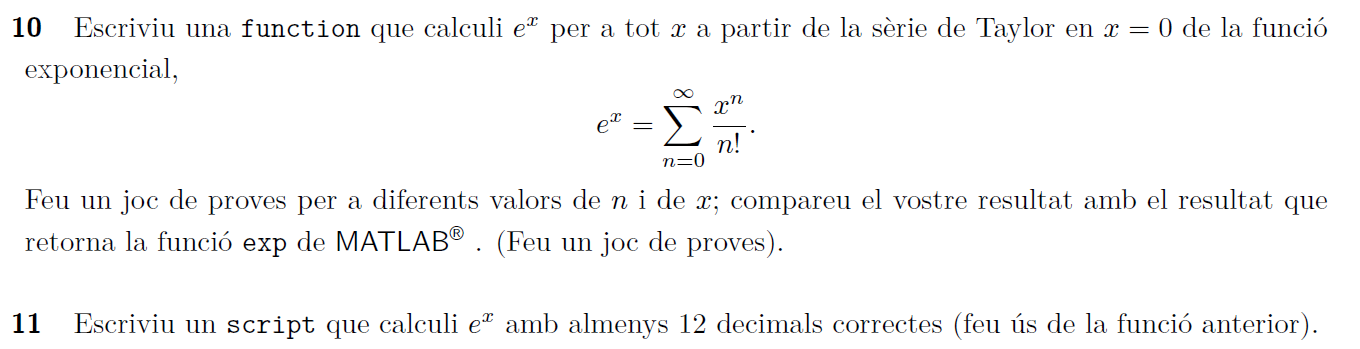 

format longG
x = 14.1; n = 40;
my_exp(x,n); my_exp(-x,n);

El falor de e^(14.1) calculat de Matlab és 1329083.28081209282391
El valor de e^(14.1) aproximat és 1329083.27494041924365; es tenen 1 decimals correctes i 8 xifres significatives

El falor de e^(-14.1) calculat de Matlab és 0.00000075239830
El valor de e^(-14.1) aproximat és 0.00000075239851; es tenen 12 decimals correctes i 6 xifres significatives



x = 3.52; n = 50;
my_exp(x,n); my_exp(-x,n);

El falor de e^(3.52) calculat de Matlab és 33.78442846384955
El valor de e^(3.52) aproximat és 33.78442846384909; es tenen 12 decimals correctes i 13 xifres significatives

El falor de e^(-3.52) calculat de Matlab és 0.02959943516789
El valor de e^(-3.52) aproximat és 0.02959943516804; es tenen 12 decimals correctes i 11 xifres significatives



x = 1.87; n = 20;
my_exp(x,n); my_exp(-x,n);

El falor de e^(1.87) calculat de Matlab és 6.48829639928671
El valor de e^(1.87) aproximat és 6.48829639928659; es tenen 12 decimals correctes i 13 xifres significatives

El falor de e^(-1.87) calculat de Matlab és 0.15412366181513
El valor de e^(-1.87) aproximat és 0.15412366181545; es tenen 12 decimals correctes i 11 xifres significatives



x = 17.22; n = 100;
my_exp(x,n); my_exp(-x,n);

El falor de e^(17.22) calculat de Matlab és 30098924.55466772615910
El valor de e^(17.22) aproximat és 30098924.55466771870852; es tenen 7 decimals correctes i 15 xifres significatives

El falor de e^(-17.22) calculat de Matlab és 0.00000003322378
El valor de e^(-17.22) aproximat és 0.00000003322413; es tenen 12 decimals correctes i 4 xifres significatives



function s = sumapi(m)
% Funció convergència a pi
x = 0;
for n = 0:m
    x = x + ((-1/3)^n)/(2*n+1);
end
s = sqrt(12)*x;
end

`Document preparat per M. Àngela Grau Gotés, 24 de febrer de 2021`